# **Machine Learning From Coursera(Week1)**

Exercise1 MultiFeatures

In this exercise, I'll programme the agorithm according to the procedures in ex1.pdf .

## **Step 1 Loading the Data and Prepare the data to be trained**

clear all;close all;clc
data=load('Data/ex1data1.txt')

data =     6.1101   17.5920
    5.5277    9.1302
    8.5186   13.6620
    7.0032   11.8540
    5.8598    6.8233
    8.3829   11.8860
    7.4764    4.3483
    8.5781   12.0000
    6.4862    6.5987
    5.0546    3.8166


x=data(:,1);    
y=data(:,2);    
m=length(y)

m = 97

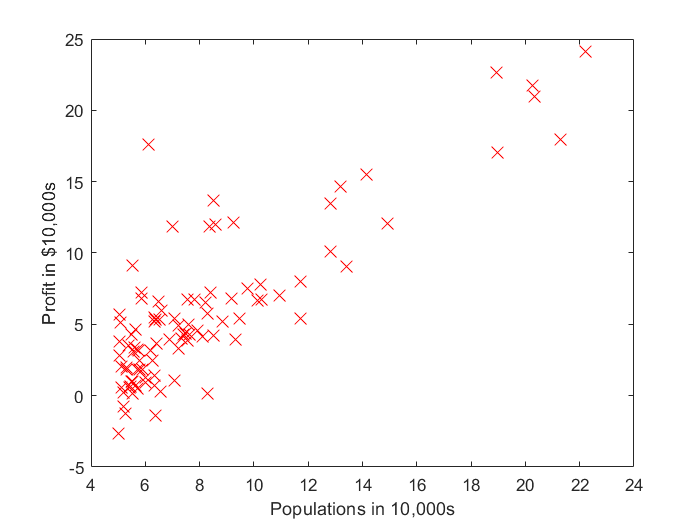

plot(x,y,'rx','MarkerSize',10)
xlabel("Populations in 10,000s");
ylabel("Profit in $10,000s")

X=[ones(m,1),x];   % adding a column of ones to x
theta=zeros(2,1);  %initialize fitting parameters
iterations=1500;
alpha=0.01;        %learning rate

## Step 2: Computer Cost 

fprintf('\nTesting the cost function...\n');        


Testing the cost function...


Cost=Cost_function(X,y,theta);           
fprintf('With theta=[0 0]\nCost Computed=%.2f\n',Cost);

With theta=[0 0]
Cost Computed=32.07


%testing the cost function
Cost=Cost_function(X,y,[-1;2]);
fprintf('With theta=[-1 2]\nCost Computed=%.2f\n',Cost);

With theta=[-1 2]
Cost Computed=54.24


## Compute Gradient Descent

[theta,J_history]=Gradient_Descent(X,y,theta,alpha,iterations);
fprintf('Theta found by gradient descent:\n');

Theta found by gradient descent:


fprintf('%.f\n',theta);

-4
1


## Step 3: Plot the Linear Fit

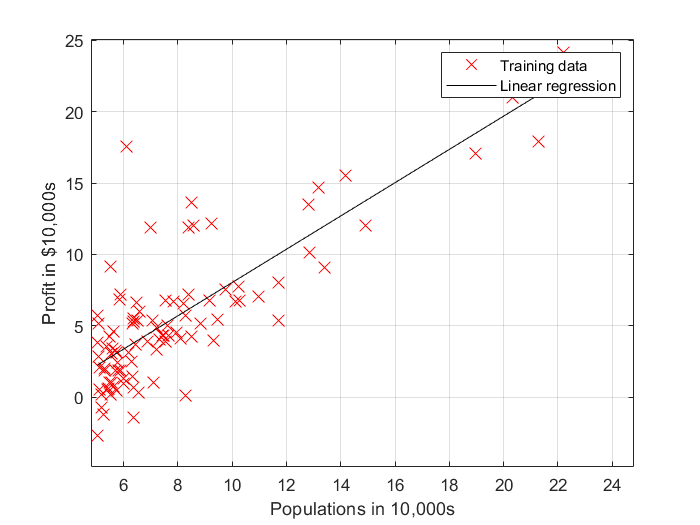

%p=polyfit(x,y,1);
%f=polyval(p,X(:,2));
hold on     
%plot(X(:,2),f,'k-')
plot(X(:,2),X*theta,'k-')                
legend('Training data','Linear regression') 
hold off
xlim([4.8 24.8])
ylim([-4.9 25.1])
grid on

% predict values for population sizes of 35,000 and 70,000
predict1=[1,3.5]*theta;
fprintf('For population = 35,000, we predict a profit of %f\n',...
    predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2=[1,7]*theta;
fprintf('For population = 70,000, we predict a profit of %f\n',...  
     predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


## Step 4: Visualizing J(theta_0,theta_1)

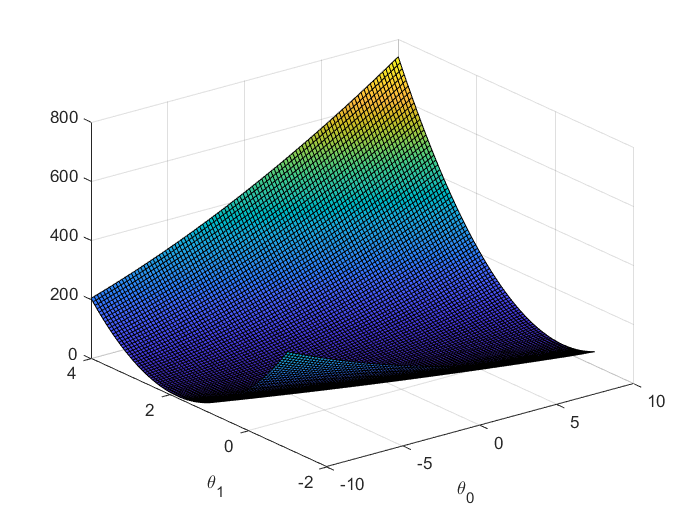

theta0_vals=linspace(-10,10,100);
theta1_vals=linspace(-1,4,100);
J_vals=zeros(length(theta0_vals),length(theta1_vals));

for i=1:length(theta0_vals)
    for j=1:length(theta1_vals)
        t=[theta0_vals(i);theta1_vals(j)];
        J_vals(i,j)=Cost_function(X,y,t);
    end
end
J_vals=J_vals';
surf(theta0_vals,theta1_vals,J_vals)
xlabel('\theta_0');ylabel('\theta_1');

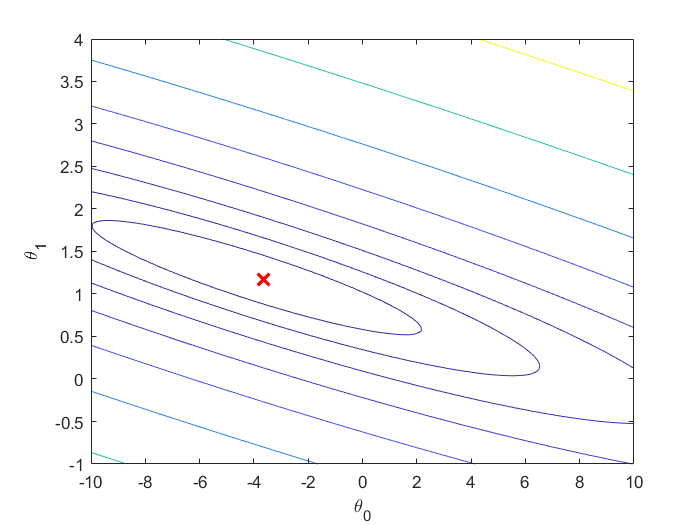

contour(theta0_vals,theta1_vals,J_vals,logspace(-2,3,20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);

function J=Cost_function(X,y,theta)  
h=X*theta;
m=length(y);
sqrError=(h-y).^2;
J=1/(2*m)*sum(sqrError);
end

%Batch Gradient Descent method
function[theta,J_history]=Gradient_Descent(X,y,theta,alpha,iterations)
m=length(y);
J_history=zeros(iterations,1);
    for iterations=1:iterations
        h=X*theta;
        temp0=theta(1)-alpha*(1/m)*sum((h-y).*X(:,1));
        temp1=theta(2)-alpha*(1/m)*sum((h-y).*X(:,2));
        theta(1)=temp0;
        theta(2)=temp1; 
        J_history(iterations) = Cost_function(X, y, theta);
    end
  
end
